# Fix the sample frequency of the EMG signal

init params

clc, clear, close all;
addpath OTHER
addpath DATASET

display_points = 1000;
base_sample_rate = 1000;
frame_size = 501;

Load the data of the EMG and the base signal

filename_base = 'pianosync.wav';
[y,Fs] = audioread(filename_base); % 8kHz sample
base_sync_1k = SigConToBin(y(:, 1)', Fs, base_sample_rate);
base_sync_1k_base = double(base_sync_1k)-0.5;
base_sync_1k = base_sync_1k_base;

filename_EMG = 'opensignals_000780589b3a_2023-12-19_11-12-23.txt';
data = readmatrix(filename_EMG, 'Range', 4, 'Delimiter', '\t');
emg_sample_rate = 1000;
emg_sync_1k = ReadEMG(data, emg_sample_rate, base_sample_rate);

Align the datapoints

[emg_sync_1k, lag_emg] = Align(base_sync_1k, emg_sync_1k);
emg_sync_1k = emg_sync_1k(lag_emg: end);
base_sync_1k = base_sync_1k(lag_emg: end);

Cut to size

min_length = floor(min([length(emg_sync_1k) length(base_sync_1k)]));
emg_sync_1k = emg_sync_1k(1:min_length);
base_sync_1k = base_sync_1k(1:min_length);

show the data where we do not have done any frequency correction

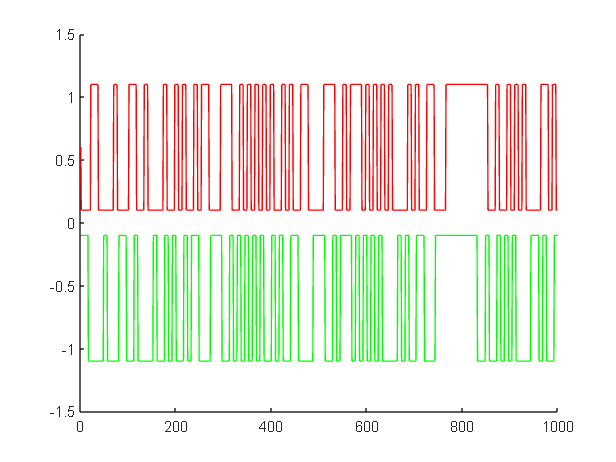

figure;
hold on;
plot(emg_sync_1k(1:display_points) +0.6, "r");
plot(base_sync_1k(1:display_points) - 0.6, "g");
hold off;

Do the correlation in begin and end of the signal to determine the difference.

%correlate beginning
[ emg_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k(1:frame_size));
%shift the signal to the correct position
[~, max_start] = max(emg_corr_start);
max_start = floor((frame_size-max_start))

max_start =     21


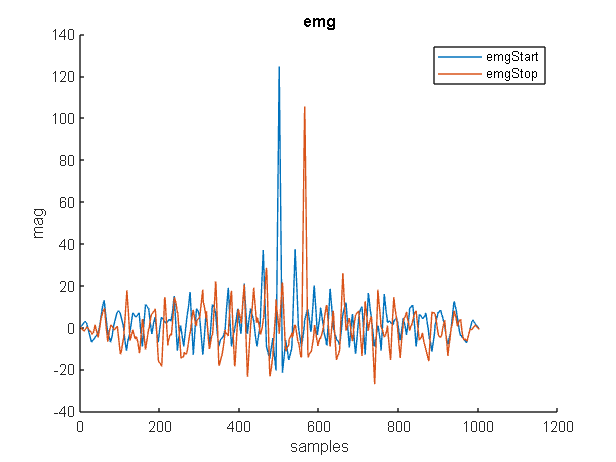


if max_start < 0
    base_sync_1k = base_sync_1k(abs(max_start): end-abs(max_start));
else
    emg_sync_1k = emg_sync_1k(abs(max_start): end-abs(max_start));
end

[ emg_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k(1:frame_size));
[~, max_start] = max(emg_corr_start);

%correlate ending based on frame_lenght
[emg_corr_end, ~] = xcorr(base_sync_1k(end-frame_size:end), emg_sync_1k(end-frame_size:end));


figure
hold on
title("emg")
plot(emg_corr_start, "DisplayName","emgStart")
plot(emg_corr_end, "DisplayName","emgStop")
xlabel("samples"); ylabel("mag");
legend()
hold off;

[~, max_start] = max(emg_corr_start);
[~, max_end] = max(emg_corr_end);
total_shift = max_end - max_start;
% new sample rate
shift_error = total_shift / length(base_sync_1k)

shift_error =       0.000392688628596322


emg_sample_rate = 1000 + shift_error;
emg_sync_1k = resample(emg_sync_1k, floor(base_sample_rate*1000), floor(emg_sample_rate*1000));


### Test it

[correlation_emg, lag_emg] = xcorr(base_sync_1k, emg_sync_1k);
correlation_emg = correlation_emg/max(correlation_emg); % normalize
correlation_emg = 20.*log10(correlation_emg); % to dB

plot(lag_emg, correlation_emg);

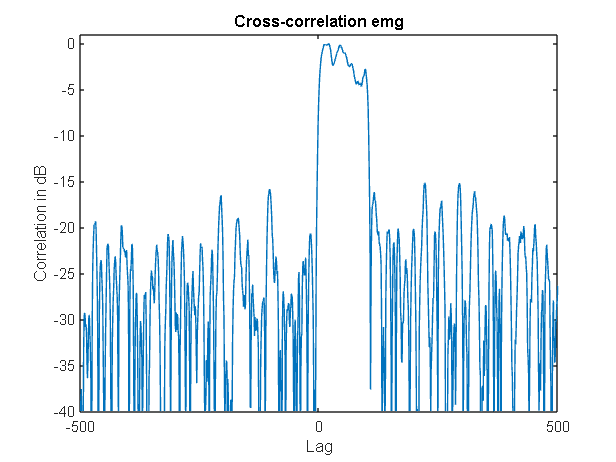

xlabel('Lag');          ylabel('Correlation in dB');
xlim([-500 500]);      ylim([-40 1]);
title('Cross-correlation emg');

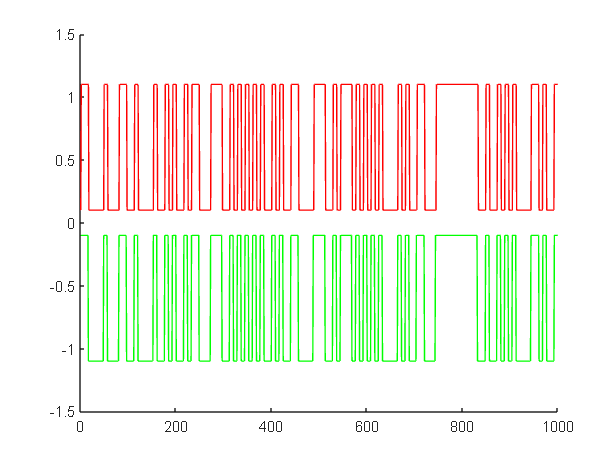

figure;
hold on;
plot(emg_sync_1k(1:display_points) +0.6, "r");
plot(base_sync_1k(1:display_points) - 0.6, "g");
hold off;


[ emg_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k(1:frame_size));
%shift the signal to the correct position
[~, max_start] = max(emg_corr_start);
max_start = floor((frame_size-max_start))

max_start =      1


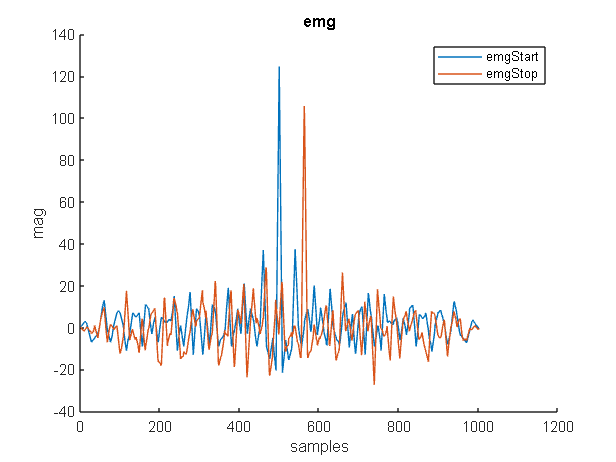


if max_start < 0
    base_sync_1k = base_sync_1k(abs(max_start): end-abs(max_start));
else
    emg_sync_1k = emg_sync_1k(abs(max_start): end-abs(max_start));
end

[ emg_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k(1:frame_size));
[~, max_start] = max(emg_corr_start);

%correlate ending based on frame_lenght
[emg_corr_end, ~] = xcorr(base_sync_1k(end-frame_size:end), emg_sync_1k(end-frame_size:end));


figure
hold on
title("emg")
plot(emg_corr_start, "DisplayName","emgStart")
plot(emg_corr_end, "DisplayName","emgStop")
xlabel("samples"); ylabel("mag");
legend()
hold off;

[~, max_start] = max(emg_corr_start);
[~, max_end] = max(emg_corr_end);
total_shift = max_end - max_start;
% new sample rate
shift_error = total_shift / length(base_sync_1k);
emg_sample_rate = 1000 + shift_error;

function [signalA, signalB] = formatSignals(signalA, signalB)

[signalB, lag_emg] = Align(signalA, signalB);
signalB = signalB(lag_emg: end);
signalA = signalA(lag_emg: end);

min_length = floor(min([length(signalB) length(signalA)]));
signalB = signalB(1:min_length);
signalA = signalA(1:min_length);

% 
% %correlate beginning
% [corr_start, ~] = xcorr(signalA(1:frameSize), signalB(1:frameSize));
% 
% %correlate ending based on frame_lenght
% [corr_end, ~] = xcorr(signalA(end-frameSize:end), signalB(end-frameSize:end));
% 
% [~, max_start] = max(corr_start);
% [~, max_end] = max(corr_end);
% total_shift = max_end - max_start;
% shift_error = total_shift / length(signalA);
% sampleRate = samp + shift_error;

end